load('Tire model/TTC data files/B1654run35.mat')

Group data:

n_data=size(ET);
scalefactor=0.6;
[loadlb,loadub]=groupdata(FZ(1:4140),4,100,1342);

Fit Pacejka function to data:

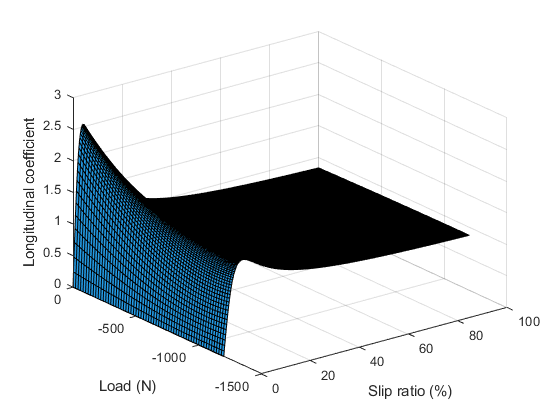


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


C=zeros(4,3);
%[SLlb,SLub]=groupdata(SL(loadlb(1):loadub(1)),3,0.19,0)
%C(2,:) = fit(SL(SLlb(2):SLub(2)),NFX(SLlb(2):SLub(2)));
C(1,:)=fit(SL(loadlb(1):loadub(1)),NFX(loadlb(1):loadub(1)));

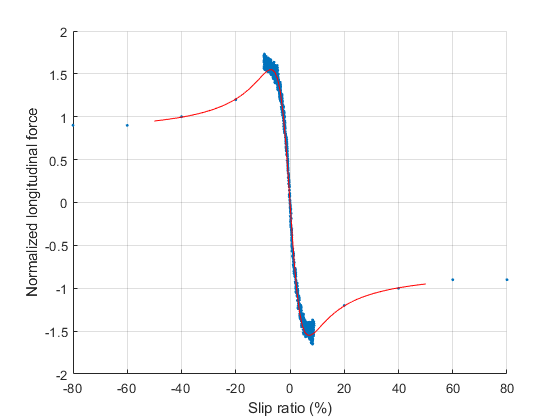


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


C(2,:)=fit(SL(loadlb(2):loadub(2)),NFX(loadlb(2):loadub(2)));

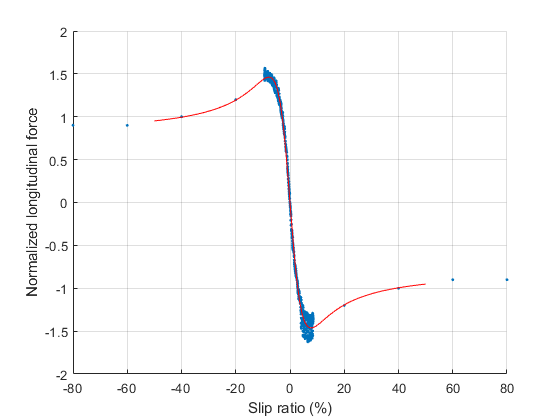


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


C(3,:)=fit(SL(loadlb(3):loadub(3)),NFX(loadlb(3):loadub(3)));

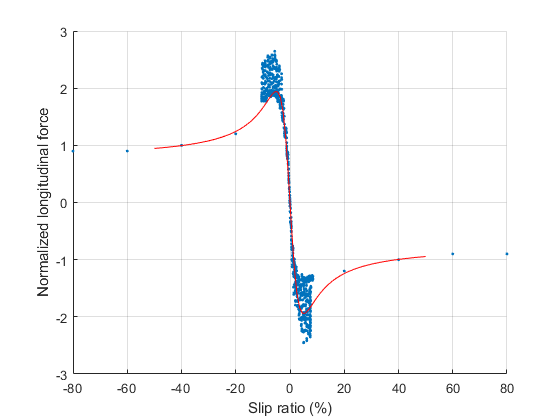


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


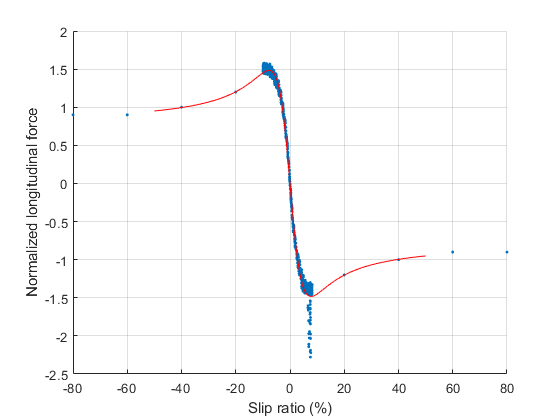

C(4,:)=fit(SL(loadlb(4):loadub(4)),NFX(loadlb(4):loadub(4)));


save('Tire model/pacejka_coefficients_longitudinal.mat',"C");

Stiffness coefficients:

% stiff=zeros(5,1);
% for j=1:5
%     stiff(j)=C(j,3)*C(j,2)*C(j,1)*(1-C(j,4));
% end
% save('longitudinal_stiffness.mat',"stiff");

Find the average value in each load group:

loads = [
    mean(FZ(loadlb(1):loadub(1))) ...
    mean(FZ(loadlb(2):loadub(2))) ...
    mean(FZ(loadlb(3):loadub(3))) ...
    mean(FZ(loadlb(4):loadub(4))) ...
    ]

loads = 	1.0e+03 *

   -0.7568   -1.0330   -0.3012   -0.8396


Load and SR step size:

d_load = 20;
d_SR = 0.002;

Take sample points of each fitted curve (curve is in row):

SR_x = 0:d_SR:1;
n_SR = length(SR_x);
sample_points = pacejka(C,SR_x);

Fit a 4-th order polynomial to each column of points (load sensitivity at each SR):

poly_coeff = zeros(3,n_SR);
for i = 1:n_SR
    poly_coeff(:,i) = polyfit(loads,sample_points(:,i),2);
end

Populate with extra load values in between the 5 given:

loadbounds = [-1200 0];
load_y = (loadbounds(1):d_load:loadbounds(2))';
n_load = length(load_y);
long_coeff = zeros(n_load,n_SR);
for j = 1:n_SR
    long_coeff(:,j) = polyval(poly_coeff(:,j),load_y);
end

Plot on a heat map:

surfl(ones(n_load,1)*100*SR_x, ...
    load_y*ones(1,n_SR), ...
    -long_coeff);
xlabel('Slip ratio (%)')
ylabel('Load (N)')
zlabel('Longitudinal coefficient')


save('Tire model/longitudinal_coeff_lut.mat', ...
    'long_coeff', ...
    'SR_x', ...
    'load_y');

## Functions

Define Pacejka function:

function y = pacejka(C,sigma)
    sigma = ones(size(C,1),1)*sigma;
    y=(C(:,3)*ones(1,size(sigma,2))).*sin((C(:,2)*ones(1,size(sigma,2))).*atan(atan((C(:,1)*ones(1,size(sigma,2))).*sigma)));
end

Fit curve for a single vertical load group:

function C = fit(kappa_unscaled,mu_unscaled)
hold off
scalefactor=0.6;
kappa = kappa_unscaled * scalefactor; % Scale the horizontal
%sigma_x = kappa./(1+kappa);
mu = mu_unscaled * scalefactor; % Scale the vertical
mu = mu*2.505/2.83; % Compensate for different tire
hold on

% Add data points to bring the curve down outside the TTC range
n_add = 500; % Number of data points
kappa_add = [0.2,0.4,0.6,0.8]; % X-position of points
nfx_add = [-1.2,-1,-0.9,-0.9];
for i=1:size(kappa_add,2)
    kappa = [kappa;kappa_add(i)*ones(n_add,1);-kappa_add(i)*ones(n_add,1)];
    mu = [mu;nfx_add(i)*ones(n_add,1);-nfx_add(i)*ones(n_add,1)];
end

% Optimization bounds
lb = -inf*ones(3,1);
ub = inf*ones(3,1);
C0 = [-0.03,-100,-1.6]; % Optimization initial value

% Optimization options
options=optimoptions('lsqcurvefit');
options.MaxFunctionEvaluations=6000;
options.MaxIterations=6000;
options.Algorithm='levenberg-marquardt';

% Optimization
[Cfinal,~,~,~,~] = lsqcurvefit(@pacejka,C0,kappa,mu,lb,ub,options);

% Plot the data
figure
hold on
scatter(kappa*100,mu,5,'filled') % Plot the data
% Plot the generated curve
x=linspace(-0.5,0.5);
%plot(x*100,pacejka(Cfinal,x./(1+x)),'red')
plot(x*100,pacejka(Cfinal,x),'red')
xlabel('Slip ratio (%)')
ylabel('Normalized longitudinal force')
grid on
hold off
C=Cfinal;
end

Grouping data:

function [lb,ub] = groupdata(data,n,range,start)
    lb=zeros(n,1);
    ub=zeros(n,1);
    lb(1)=1;
    x = 0;
    for i=1:n
        if i>1
            lb(i)=ub(i-1)+1;
        end
        while 1
            x=x+1;
            if (x >= size(data,1)) || (abs(data(x) - data(x+1)) > range)
                ub(i)=x;
                break
            end
        end
    end
    lb=lb+start*ones(n,1);
    ub=ub+start*ones(n,1);
end
